## **Shear Flow and Skin Thickness**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

%-----------------------------------------------------------------------------%
%%% 0 Design Parameters

%% 0.1 Sea Level
[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

%% 0.2 Fuselage Properties
D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)

%% 0.3 Material Properties
sigma_y = 455;                     % Tensile yield stress (MPa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (MPa)

%% 0.4 Critical Loading Conditions
Q = 5.951582721709430e+05;         % Maximum shear force (N)
P = 0;                             % Maximum tangential load (N)
M = -5.067912648168767e+06;        % Maximum bending moment (Nm)
T = 1.263599895277778e+06;         % Maximum torque (Nm)

%-----------------------------------------------------------------------------%
%%% 1 Calculate the Shear Flow

%% 1.1 Calculate the Shear Flow Distribution

% Define starting point
theta = 0;
alpha = 0;

q = zeros(1, 36000);


% Use iteration method
for i = 1 : 36000

    q(i) = (T + P * r) / (2 * pi * r ^ 2) + P * cos(deg2rad(theta - alpha)) / (pi * r) + Q * sin(deg2rad(theta - alpha)) / (pi * r);

    theta = theta + 360 / 36000;

end

% Check the result
min(q)

ans = -3.9624e+04

max(q)

ans = 7.9150e+04


%% 1.2 Plot the Shear Flow Distribution

% Create q matrix for plot
theta = 0;
q_plot = zeros(1, 90);

for i = 1 : 90

    q_plot(i) = (-T + P * r) / (2 * pi * r ^ 2) + P * cos(deg2rad(theta - alpha)) / (pi * r) + Q * sin(deg2rad(theta - alpha)) / (pi * r);

    theta = theta + 360 / 90;

end

% Check the result
min(q_plot)

ans = -7.9114e+04

max(q_plot)

ans = 3.9588e+04

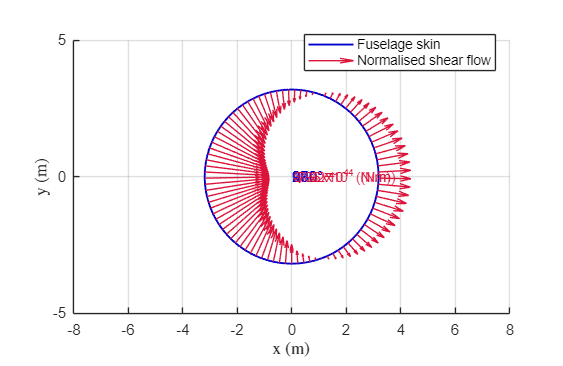


% Plot in Cartesian coordinate
theta = linspace(-pi / 2, 3 * pi / 2, 90);
x = r * cos(theta);
y = r * sin(theta);

% Scale normal vectors by magnitude
ux = q_plot .* cos(theta); % in x
uy = q_plot .* sin(theta); % in y

figure(1)

clf;

hold on;

plot(x, y, 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25); % Fuselage boundary
quiver(x, y, ux, uy, 2.5, 'Color', [220/255 20/255 60/255]);   % Arrows

txt1 = 'q_{max} = ';
txt7 = '-7.92x10^4 (N/m)';
txt2 = 'q_{min} = ';
txt8 = '3.96x10^4 (N/m)';
txt3 = '0°';
txt4 = '90°';
txt5 = '180°';
txt6 = '270°';

text(0, 0, txt1, 'Color', [220/255 20/255 60/255], 'FontSize', 9)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 9)
text(0, 0, txt3, 'Color', [0/255 0/255 205/255], 'FontSize', 10)
text(0, 0, txt4, 'Color', [0/255 0/255 205/255], 'FontSize', 10)
text(0, 0, txt5, 'Color', [0/255 0/255 205/255], 'FontSize', 10)
text(0, 0, txt6, 'Color', [0/255 0/255 205/255], 'FontSize', 10)
text(0, 0, txt7, 'Color', [220/255 20/255 60/255], 'FontSize', 9)
text(0, 0, txt8, 'Color', [220/255 20/255 60/255], 'FontSize', 9)

% Legends
legend("Fuselage skin", "Normalised shear flow", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
axis equal;
xlim([-8 8]);
ylim([-5 5]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);



%% 1.3 Calculate the skin lower bound

thickness = max(abs(q)) / (tau_y * 10e5)

thickness = 3.0130e-04


thickness * 1000

ans = 0.3013